# Model of a single neuron

The following matlab notebook has been written by Charles Burns in completion of the computational neuroscience course.

This document will follow the worksheet point by point for simplification. May be later rewritten as a short report.

The content is indirectly based on Dayan & Abbott (2001) Theoretical Neuroscience (Sections 5.1-5.4, 5.8-5.9).

The model of the membrane potential of a single neuron is derived from a simple system of equations:


$$$$V(0)=0 \quad\quad \quad\quad \quad (1)\\\ dV=(I-GV) dt \quad  \text{ (2)$$


where $V(t)$ is the voltage at time $t$, $I(t)$ is an input current at time $t$, and $G$ is the leak conductance (assumed constant), and $dt$ is a small change in time. This system of equations can be solved by:


$$V(t+dt)=V(t) +dt(I-G\cdot V(t)) \quad (3)
$$


## 1. A simple integrate and fire model

Below we include the code to implement an integrate and fire model, assuming no refractory period. We implement the following equation:


$$\tau_m \frac{dV}{dt}=E_L-V+R_mI_e \quad (1)$$


and its solution for the *subthreshold* membrane potential at time $t$, given a membrane resistance $R_m$, input current $I_e$ and:


$$V(t)=E_L+R_mI_e+(V(0)-E_L-R_mI_e)\exp(-t/\tau_m) \quad (2)
$$


therefore, when$V(t)$ reaches $V$, our code will reset to the equilibrium potential in the next timestep. 

We define a **function** `IntegrateFire.m`

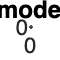

%Integrate and fire model of a single neuron.

%Parameters         Unit,     description
tau_m = 10*10^(-3);  %Seconds, membrane time constant
El = -70*10^(-3);   %Volt,    equillibrium potential due to leak channels
Vfire = -40*10^(-3);%Volt,    action potential threshold
Rm = 10*10^6;       %Ohm,     membrane resistance 
I = 3.1*10^(-9);    %Ampere,  current for simulated input
dt = 10^(-3);       %Seconds, timestep for sampling voltage.
tMax = 1;           %Seconds, end of sampling period.

mV = IntegrateFire(dt,tMax,tau_m,El,Rm,I,Vfire)*1000; %run simulation, scale to mV
times = [0:dt:tMax].*1000; %timepoints in ms

plot(times,mV); %plot membrane potential against time. We adjust the plot below:
xlabel('Time (ms)');
ylabel('Membrane potential (mV)');
ylim([-90,0]); %manual rescaling of y-axis
yline(Vfire*1000,'r-', 'threshold') %plot threshold in mV
yline(El*1000,'--', 'equillibrium', 'LabelVerticalAlignment','bottom') %equillibrium in mV
title('Integrate and fire model (without spiking)')

#### 2. Analytical computation

Given the initial conditions in the code block above, what's the minimum input current for the cell to reach the threshold potential?

We can consider the convergence of the membrane potential in an attractor state, namely a local minima of the gradient of the membrane potential, $V^*$. Rearranging equation $(1)$ above and setting $\frac{dV}{dt}=0$, we obtain the following:


$$\frac{dV}{dt}=\frac{1}{\tau_m}(E_L-V+R_mI_e) \\
\Rightarrow 0=\frac{1}{\tau_m}(E_L-V^*+R_mI_e) \\
\Rightarrow V^*=E_L+R_mI_e

$$


Inputting the conditions from the codeblock in part one will result in $V^*= -39mV$, confirming that our neuron does reach the threshold in our simulations. 

More generally, the neuron fires when $V^*>V_{th}$, which let's us rearrange the above for a condition on the input current, $I_e$:


$$I_e>\frac{V_{th}-E_L}{R_m}$$


Which, given our initial conditions will result in $I_{e}>3nA$.

minimumCurrent = (Vfire-El)/Rm

#### 3. Rerunning integrate and fire model

Here we re-run the integrate and fire model but *just below* the analytically derived minimum current for firing. From the figure below, we see that this neuron never fires.

%Parameters from Code 1.2 apply here.

I2 = minimumCurrent; %0.1 nA lower than before, below threshold.
%We run the simulation with a new current and rescale to mV:
mV2 = IntegrateFire(dt,tMax,tau_m,El,Rm,I2,Vfire)*1000; 
times = [0:dt:tMax].*1000; %timepoints in ms

plot(tMax,mV2); %
xlabel('Time (ms)');
ylabel('Membrane potential (mV)');
ylim([-90,0]);
yline(Vfire*1000,'r-', 'threshold')
yline(-70,'--', 'equillibrium','LabelVerticalAlignment','bottom')
title('Integrate and fire model (without spiking)')
subtitle('Input current = ' + string(minimumCurrent) +'A')

#### 4. Firing rate as a function of input current

Following the worksheet instructions, we run another integrate and fire model, but this time we vary the input current and plot the firing rates.

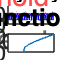

%Parameters from step 1 apply here.

currentBin = [2:0.1:5]*10^(-9); %Amperes, the input current binned in 0.1 steps.

%Initialise matrices:
V3 = zeros(length(times),length(currentBin)); %we store V for each current
firingRate = zeros(length(currentBin),1); %initialise firing rate

for i = 1:length(currentBin)
    %We run the simulation with the current indexed out:
    V = IntegrateFire(dt,tMax,tau_m,El,Rm,currentBin(i),Vfire);
    firingRate(i) = sum(V>Vfire)/tMax; %Firing rate in Hz.
end

plot(currentBin*10^9,firingRate) %scaling x-axis to nA
xlabel('Input current (nA)')
ylabel('Firing Rate (Hz)')
title('Firing rate as a function of input current')

#### 5. Synaptic connections in neurons

This is our first step real step towards attractor dynamics in recurrent neural networks. We make basic assumptions about the neuronal parameters and see how their voltages will dynamically change.

**We define a function: **`IntegrateFire2.m`

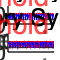

%Parameters - the same for both neurons. dt and tMax as above.

tau_m = 20*10^(-3);     %Seconds, membrane time constant
El = -70*10^(-3);       %Volt, equilibrium potential due to leak channels
Vreset = -80*10^(-3);   %Volt, the reset potential
Vth = -54*10^(-3);      %Volt, the threshold potential
RI = 18*10^(-3);        %Membrane resistance times input
RG = 0.15;              %Synapse resistance and conductance
Pmax = 0.5;             %probability, max synaptic opening probability
tau_s = 10*10^(-3);     %time constant for the synapse 'closing'.

%Excitatory synapses:
Es = 0;
Vexcite = IntegrateFire2(Es,dt,tMax,tau_m,El,RI,Vth,Vreset,tau_s,RG,Pmax);

%Inhibitory synapses:
Es = -80*10^(-3);
Vinhibit = IntegrateFire2(Es,dt,tMax,tau_m,El,RI,Vth,Vreset,tau_s,RG,Pmax);

times = [0:dt:tMax].*1000; %rescaling timepoints to ms

figure; 
subplot(2,1,1);
hold on;
plot(times,Vexcite(:,1)*1000,'r')
plot(times,Vexcite(:,2)*1000,'b')
xlabel('Time (ms)');
xlim([0,times(end)]);
ylabel('Membrane potential (mV)');
ylim([-100,-20]); %rescaling y-axis manually
yline(Vth*1000,'r-', 'threshold')
yline(Vreset*1000,'--', 'reset', 'LabelVerticalAlignment','bottom')
subtitle('Excitatory Synapses')
hold off

subplot(2,1,2); hold on;
plot(times,Vinhibit(:,1)*1000,'r')
plot(times,Vinhibit(:,2)*1000,'b')
xlabel('Time (ms)');
xlim([0,times(end)]);
ylabel('Membrane potential (mV)');
ylim([-100,-20]); %rescaling y-axis manually
yline(Vth*1000,'r-', 'threshold')
yline(Vreset*1000,'--', 'reset', 'LabelVerticalAlignment','bottom')
subtitle('Inhibitory Synapses')
hold off;